# Mutual information of written English text

In this extension activity, we will continue our analysis of written English extracted from the [Seinfeld](https://en.wikipedia.org/wiki/Seinfeld) scripts as begun in the previous module.

# Preparing your environment

As per [entropyOfCharacters.mlx](matlab:open('./entropyOfCharacters.mlx')), you may need to add your entropy scripts to the path for Matlab, e.g. using `addpath('../EntropyScripts/');` where you supply the path to your entropy scripts or the completed ones; i.e. you may need to change the folder referenced below:

pathToEntropyScripts = '../../Module01-Entropy/MatlabSimpleFunctions/completed';
addpath(pathToEntropyScripts);

# Mutual information between successive letters in written English

1. Download the data from the links on Module 2, load into Matlab and preprocess as per steps 1-4 of the activity [entropyOfCharacters.mlx](matlab:open('./entropyOfCharacters.mlx')) from the previous module, such that we have the characters stored in the array `processedStr:`

*Note:* you may need to alter the filename/path to match your own --

str = fileread('./Seinfeld-scripts-textOnly.txt');
processedStr = regexprep(str, '[!"#$%&''()\*,-./;<=>?\[\\\]_`{}~]', ''); % Remove punctuation characters
processedStr = regexprep(processedStr, '[0-9]', ''); % Removed digits
processedStr = replace(processedStr, newline, ' '); % Replace newline characters with spaces
processedStr = lower(processedStr); % Convert all upper case into lower case
unique(processedStr)

ans = ' abcdefghijklmnopqrstuvwxyz'

2. How can we now compute the mutual information between one character and the character that comes next in the text? We will need to provide samples of a previous character and the next character to our `mutualinformationempirical()` function.

*Hint*: to select all but the last item in an array `x`, you can refer to `x(1:end-1)`, whilst to select all but the first item in an array `x`, you can refer to `x(2:end)`

% Compute the mutual information between successive characters:
mutualinformationempirical(processedStr(1:end-1), processedStr(2:end))

ans = 0.7196

3. Compare the mutual information you computed above to the average entropy of each character computed as per step 5 of the activity in the previous module ([entropyOfCharacters.mlx](matlab:open('./entropyOfCharacters.mlx'))). Consider the following:

- What proportion of our uncertainty about the next character in the written text is reduced by observing the previous character?

- How much code could we save in communicating a character if our coding scheme took the previous character into account?

- The mutual information computes a measure of the relationship between the consecutive characters here. You're probably familiar with using correlation to measure a relationship between variables -- could correlation be used here? We will see more about how MI and correlation are related in the coming weeks.

4. Are there relationships between previous characters and later characters beyond those which are consecutive?

Can you modify your call to `mutualinformationempirical()` above to compute the mutual information between characters that are not consecutive but separated by a lag of 2 (i.e. with one character in between them)? Is there still a substantial relationship? Is this information solely contained in the earlier character or is it perhaps also included in the immediately previous character?

% Compute the mutual information between characters separated by a lag of two:
mutualinformationempirical(processedStr(1:end-2), processedStr(3:end))

ans = 0.3280

5. Can you see how this relationship changes over longer lags still? Plot the mutual information as a function of lag (up to say 10). (This may take up to a minute to run). At what point would you say there is no longer a relationship? We will discuss statistical approaches to answering that in the coming weeks.

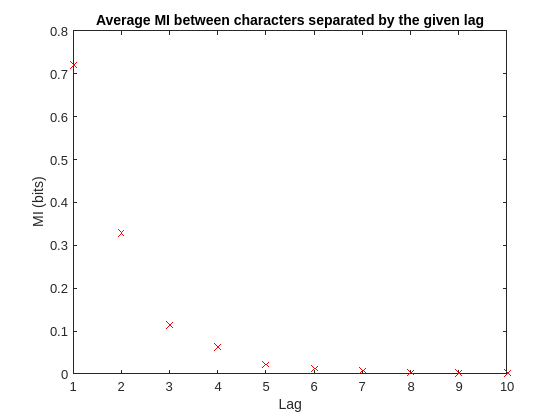

% Compute and plot the MI as a function of lag:
maxLag = 10;

misVsLag = zeros(1, maxLag);

for lag=1:maxLag
    misVsLag(lag) = mutualinformationempirical(processedStr(1:end-lag), processedStr(1+lag:end));
end

plot(1:maxLag, misVsLag, 'rx');
xlabel('Lag')
ylabel('MI (bits)');
title('Average MI between characters separated by the given lag');

# Pointwise mutual information between successive letters in written English

*Further challenge* -- It would be interesting to inspect the **local or pointwise mutual information** between each possible pair of consecutive letters. (See Part 3 of the lecture)

1. To do this, first note how `jointentropyempirical()` in [jointentropyempirical.m](matlab:open('../../Module01-Entropy/MatlabSimpleFunctions/jointentropyempirical.m')) returns the set of symbols and their probabilities, as well as the joint entropy value.

2. Now we will alter `mutualinformationempirical()` in [mutualinformationempirical.m](matlab:open('../../Module01-Entropy/MatlabSimpleFunctions/mutualinformationempirical.m')) to retrieve and return all of the relevant probabilities for each consecutive character pair: (these are already implemented in the [solution code](matlab:open('../../Module01-Entropy/MatlabSimpleFunctions/completed/mutualinformationempirical.m')))

- Alter the call for the joint entropy in `mutualinformationempirical()` to:

- Similarly, alter the call for the Y entropy to:

            and the call for the X entropy to:

- Then alter the method signature so that all of these relevant values are returned:

`3. `Next, call `mutualinformationempirical()` again as per step 2 of the previous exercise for lag 1, but this time storing all of these return values

% Call the mutualinformationempirical() function again, this time storing all of the return values.
[result, jointSymbols, jointProbabilities, xSymbols, xProbabilities, ySymbols, yProbabilities] = mutualinformationempirical(processedStr(1:end-1), processedStr(2:end));

4. Now, we loop over all possible joint symbols and compute the pointwise mutual information -- uncomment and complete the line of the code marked with `???` to compute the pointwise MI and then run this code block:

pointwiseMIs = zeros(length(xSymbols), length(ySymbols)); % Create array to store the pointwise MI values for each possible character pair
for firstCharIndex = 1:length(xSymbols)
    firstChar = xSymbols(firstCharIndex);
    probFirst = xProbabilities(firstCharIndex);
    for secondCharIndex = 1:length(ySymbols)
        secondChar = ySymbols(secondCharIndex);
        probSecond = yProbabilities(secondCharIndex);
        jointSymbolIndex = find((jointSymbols(:,1) == firstChar) & (jointSymbols(:,2) == secondChar));
        if isempty(jointSymbolIndex)
            pointwiseMIs(firstCharIndex, secondCharIndex) = 0; % No occurence, so set to 0
            continue;
        end
        probJoint = jointProbabilities(jointSymbolIndex);
        % Compute the pointwise MI from probJoint, probFirst and probSecond
        pointwiseMIs(firstCharIndex, secondCharIndex) = log2( probJoint ./ (probFirst .* probSecond) );
    end
end

5. Can you plot these values using `imagesc`? Run the command `colorbar` to insert a colour bar to show the scale. The plot will have the first letters along the y axis, and second letters along the x axis. You can label these using: 

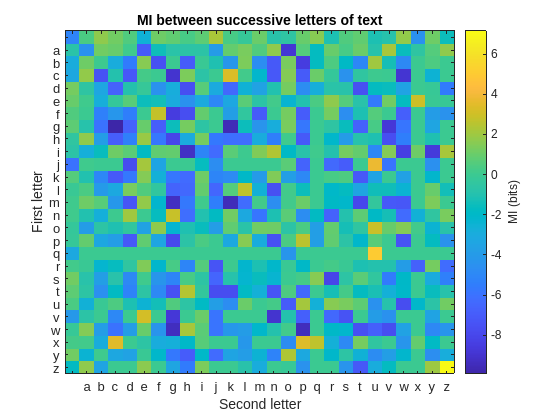

% Make the heatmap plot:
imagesc(pointwiseMIs)
% Add the labels pasting in the code from above:
ylabel('First letter');
xlabel('Second letter');
h = colorbar;
h.Label.String = 'MI (bits)';
h.Label.Rotation = 90;
xticks(1:27);
xticklabels(ySymbols);  % second letters - y - goes on x axis
h = gca();
h.XTickLabelRotation = 0; % Align the x labels properly
yticks(1:27);
yticklabels(xSymbols); % first letters - x - goes on y axis
title('MI between successive letters of text');

6. Examine the values and determine whether you can identify character pairs where the second is highly predictable from the first, and where the first character is *misinformative* about the second. Can you explain these results?